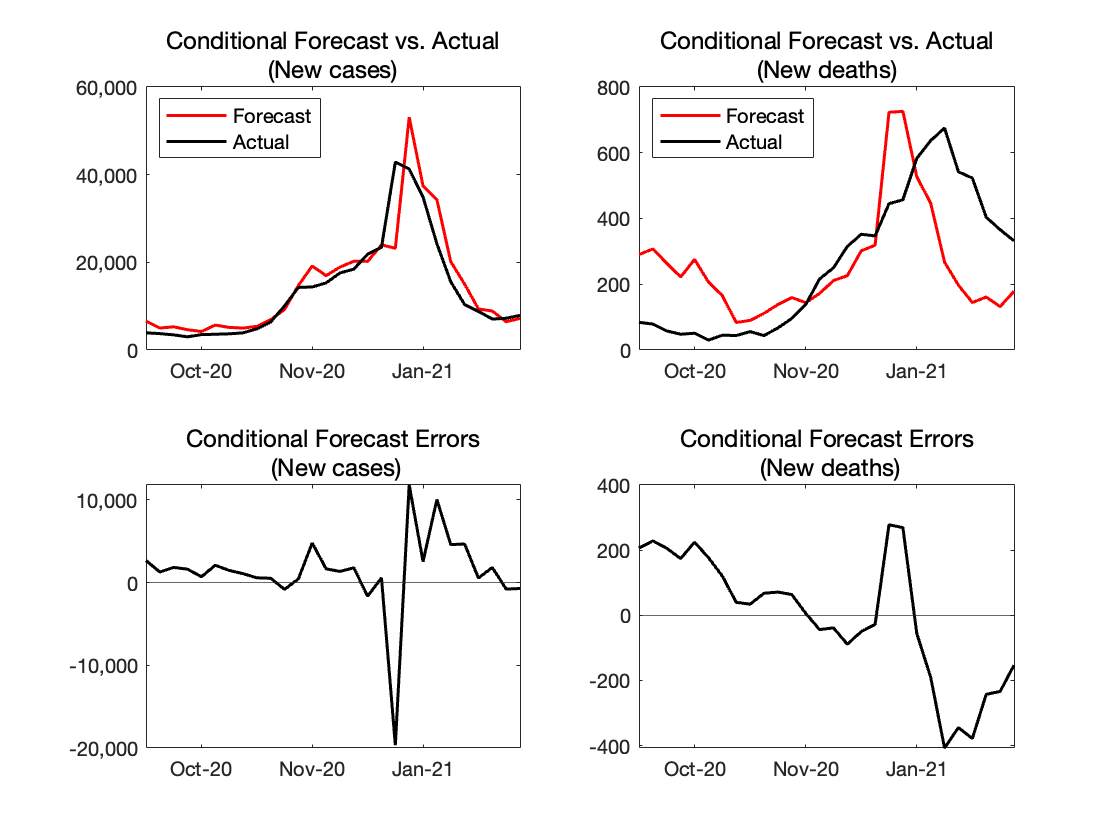

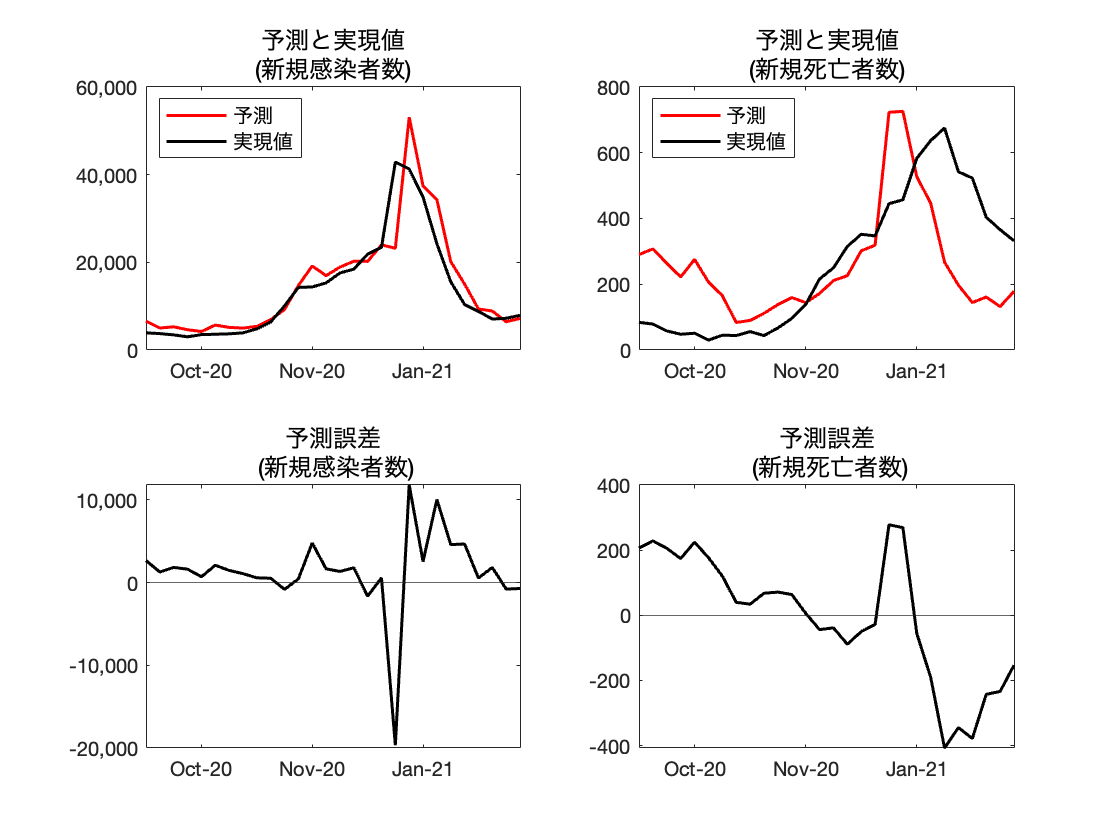


clear variables
iPC=0;
if iPC==1
    load('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Forecast.mat')
    CurrentD = load('\Users\shcor\Dropbox\fujii_nakata\Website\Codes\Forecast.mat');
else
    load('/Users/shotaro/Dropbox/fujii_nakata/Website/Codes/Forecast.mat')
    CurrentD = load('/Users/shotaro/Dropbox/fujii_nakata/Website/Codes/Japan20210316.mat');
end

Tdata = CurrentD.Tdata;
Month = CurrentD.Month;

figure_save = 1;
data_save = 1;

StartDateF  = 33;

format short
xtick1_F=StartDateF+4:8:Tdata;
xtick4_F=StartDateF+4:8:Tdata;
fs_F=10;
fs_legend_F=10;
fs_title=12;
for l = 1:2
    if l == 1
        figure(10)
    elseif l == 2
        figure(101)
    end
    subplot(2,2,1)
    plot(StartDateF:(Tdata),dNForecast(StartDateF:Tdata,1),'r',StartDateF:(Tdata),dNActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
    if l == 1
        title({'Conditional Forecast vs. Actual';'(New cases)'},'FontSize',fs_title,'FontWeight','normal')
        legend('Forecast','Actual','FontSize',fs_legend_F,'Location','Northwest')
    elseif l == 2
        title({'予測と実現値';'(新規感染者数)'},'FontSize',fs_title,'FontWeight','normal')
        legend('予測','実現値','FontSize',fs_legend_F,'Location','Northwest')
    end
    xlim([StartDateF (Tdata)])
    xticks(xtick1_F)
    xticklabels(Month(xtick1_F))
    ax = gca;
    ax.YAxis.Exponent = 0;
    ax.YAxis.FontSize = fs_F;
    ax.XAxis.FontSize = fs_F;
    ytickformat('%,6.0f')
    
    subplot(2,2,2)
    plot(StartDateF:(Tdata),dDForecast(StartDateF:Tdata,1),'r',StartDateF:(Tdata),dDActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
    if l == 1
        title({'Conditional Forecast vs. Actual';'(New deaths)'},'FontSize',fs_title,'FontWeight','normal')
        legend('Forecast','Actual','FontSize',fs_legend_F,'Location','Northwest')
    elseif l == 2
        title({'予測と実現値';'(新規死亡者数)'},'FontSize',fs_title,'FontWeight','normal')
        legend('予測','実現値','FontSize',fs_legend_F,'Location','Northwest')
    end
    ax = gca;
    ax.YAxis.FontSize = fs_F;
    ax.XAxis.FontSize = fs_F;
    ax.YAxis.Exponent = 0;
    ytickformat('%,6.0f')
    xlim([StartDateF (Tdata)])
    xticks(xtick1_F)
    xticklabels(Month(xtick1_F))
    subplot(2,2,3)
    plot(StartDateF:(Tdata),dNForecast(StartDateF:Tdata,1)-dNActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
    if l == 1
        title({'Conditional Forecast Errors',' (New cases)'},'FontSize',fs_title,'FontWeight','normal')
    elseif l == 2
        title({'予測誤差',' (新規感染者数)'},'FontSize',fs_title,'FontWeight','normal')
    end
    xlim([StartDateF (Tdata)])
    xticks(xtick1_F)
    xticklabels(Month(xtick1_F))
    yline(0)
    ax = gca;
    ax.YAxis.FontSize = fs_F;
    ax.XAxis.FontSize = fs_F;
    ax.YAxis.Exponent = 0;
    ytickformat('%,6.0f')
    subplot(2,2,4)
    plot(StartDateF:(Tdata),dDForecast(StartDateF:Tdata,1)-dDActual(StartDateF:Tdata,1),'k','LineWidth',1.5)
    if l == 1
        title({'Conditional Forecast Errors',' (New deaths)'},'FontSize',fs_title,'FontWeight','normal')
    elseif l == 2
        title({'予測誤差',' (新規死亡者数)'},'FontSize',fs_title,'FontWeight','normal')
    end
    xlim([StartDateF (Tdata)])
    xticks(xtick1_F)
    xticklabels(Month(xtick1_F))
    yline(0)
    ax = gca;
    ax.YAxis.FontSize = fs_F;
    ax.XAxis.FontSize = fs_F;
    ax.YAxis.Exponent = 0;
    ytickformat('%,6.0f')
end

if figure_save == 1
    saveas(figure(10),'/Users/shotaro/Dropbox/fujii_nakata/Website/Codes/Figures/ForecastErrors.png');
    saveas(figure(101),'/Users/shotaro/Dropbox/fujii_nakata/Website/Codes/Figures/ForecastErrors_jp.png');
end


if data_save == 1
    FE_table = round([dNForecast(end),dNActual(end),dNForecast(end)-dNActual(end);dDForecast(end),dDActual(end),dDForecast(end)-dDActual(end)]);
    FET = table(["Forecast","Actual","Error";FE_table]);
    writetable(FET,'/Users/shotaro/Dropbox/fujii_nakata/Website/Codes/ForecastTable.xls','WriteVariableNames',false);
end





